## 1 a)

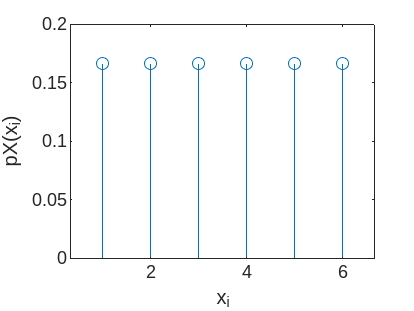




   Sx = 1:6;
   pX = ones(1,6)/6;
   stem(Sx,pX)
   xlabel("x_i")
   ylabel("pX(x_i)")

## 1 b)

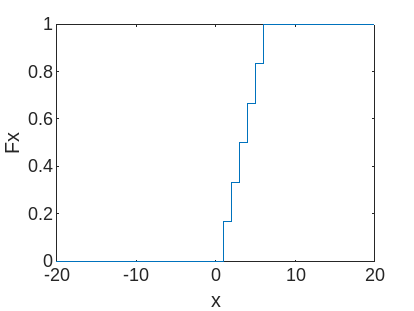


   Sx = 1:6;
   x = [-20 -10 0 Sx 7 10 20];
   pX = ones(1,6)/6;
   aux = [0 0 0 pX 0 0 0];
   Fx = cumsum(aux);
   stairs(x,Fx)
   xlabel("x");
   ylabel("Fx");

## 2 a)

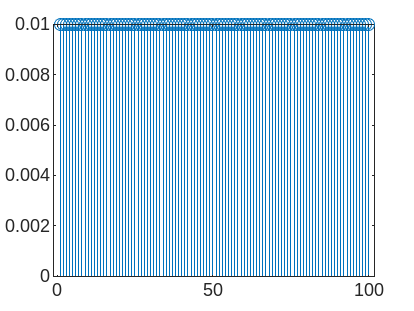


    clear
    Sx = 1:100;
    pX = ones(1,100)/100;
    stem(Sx,pX)

## 2 b) c)

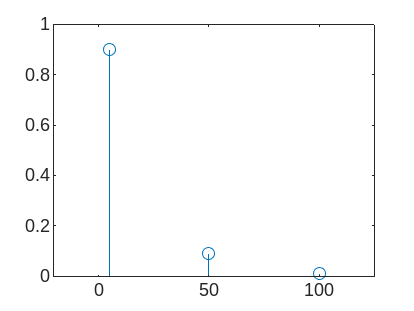



    Sx = [5 50 100];
    pX = [90 9 1]/100;
    stem(Sx,pX)

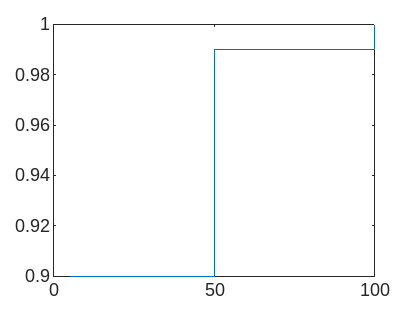


    x = Sx;
    aux = pX;
    Fx = cumsum(aux);
    stairs(x,Fx)

## 3 a) Função massa probabilidade

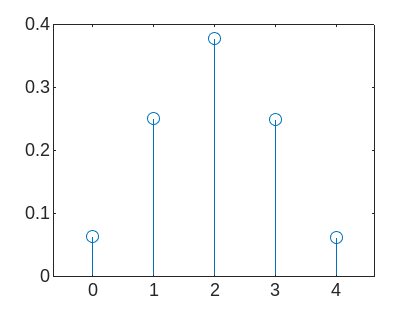



    clear
    Sx = 0:4;
    pX = [moedas(0,4,.5,1e5),moedas(1,4,.5,1e5),moedas(2,4,.5,1e5),moedas(3,4,.5,1e5),moedas(4,4,.5,1e5)];
    stem(Sx, pX)

## 3 b) Valor esperado


    
    V = sum(Sx.* pX) % V = Sx.*Px'

V = 1.9935

## 3 c)



    y = (Sx-V).^2;
    VarX = y * pX'

VarX = 0.9970

    
    % ou

    V2 = Sx.^2 * pX';
    VarX = V2 - V.^2

VarX = 0.9996

## 3 d)

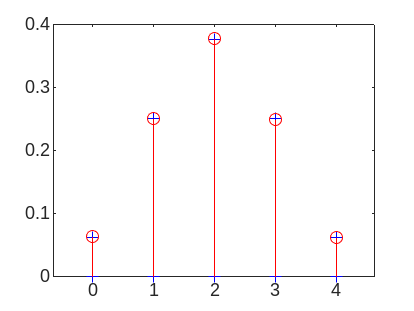


    pt = zeros(length(Sx));
    i = 1;
    n = 4;
    p = 0.5;
    for k = Sx
        pt(i) = nchoosek(n,k) * p^k * (1-p)^(n-k);
        i = i + 1;
    end

    plot(Sx,pt,'b+')
    hold on
    stem(Sx,pX,'r')
    hold off

## 3 e) E[x] Var[X]


    
    E = n * p

E = 2

    VarX = n * p * (1-p)

VarX = 1

## 3 f)

## i)


cond = Sx >= 2;
i = sum(pX(cond))

i = 0.6863

## com Fx


Fx = cumsum(pX)

Fx =     0.0633    0.3130    0.6897    0.9378    0.9993


1-Fx(Sx==2)

ans = 0.3103

## ii)



cond = Sx <= 1;
ii = sum(pX(cond))

ii = 0.3130

## com Fx

Fx(Sx==1)

ans = 0.3130

## iii)



cond = Sx >= 1;
cond1 = cond <= 3;
iii = sum(pX(cond1))

iii = 0.9993

## com Fx

Fx(Sx==3) - Fx(Sx==1)

ans = 0.6248

## 4 a)

## i)

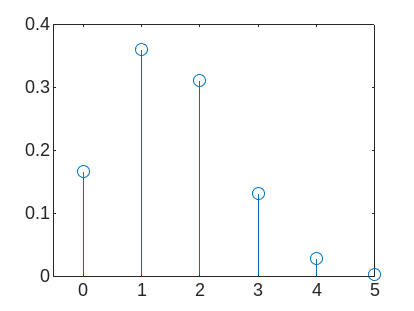


N = 1e5;
p = 30/100;
exp = rand(5,N) < p;

pX = zeros(1, 6);

for i = 0:5
    num = sum(sum(exp) == i);  
    pX(i+1) = num / N;      
end

Sx = 0:5;

stem(Sx, pX)
axis([-0.5 5 0 0.4])

## ii)

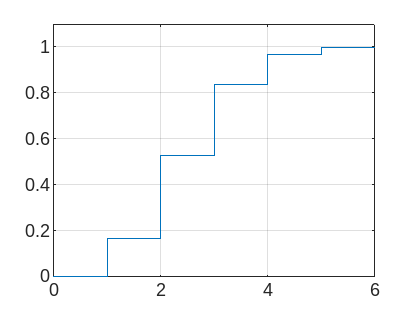


pXstairs = cumsum(pX);
stairs([Sx 6 6], [0 pXstairs 1])
axis([0 6 0 1.1])
grid on

## iii)

p = pX(1) + pX(2) + pX(3) % Prob 2 peças defeituosas no maximo

p = 0.8371

## b)

## i)

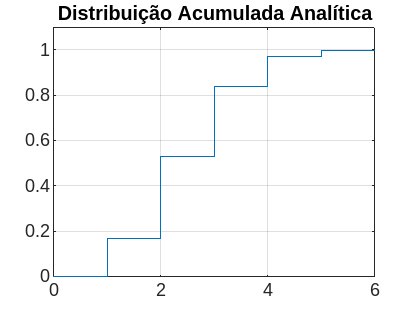

p = 30/100;

pX = zeros(1, 6);  

for i = 0:5
    pX(i+1) = pT(i, 5, p);
end

Sx=0:6;

pXstairs = cumsum(pX);
stairs([Sx 6], [0 pXstairs 1])
axis([0 6 0 1.1])
grid on
title('Distribuição Acumulada Analítica')

## ii)

p = pX(1) + pX(2) + pX(3)

p = 0.8369

## 5

N=1e6;
M2=rand(2,N);
M4=rand(4,N);

p = logspace(-3,log10(1/2),100)

p =     0.0010    0.0011    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0023    0.0024    0.0026    0.0027    0.0029    0.0031    0.0033    0.0035    0.0037    0.0040    0.0042    0.0045    0.0048    0.0051    0.0054    0.0058    0.0062    0.0066    0.0070    0.0075    0.0079    0.0085    0.0090    0.0096    0.0102    0.0109    0.0116    0.0123    0.0131    0.0140    0.0149    0.0158    0.0169    0.0180    0.0191    0.0204    0.0217



falhar2=M2<.3;
falhar4=M4<.3;

% se mais de metade não funcionar, cai
c2 = sum(sum(falhar2)>1);
c4 = sum(sum(falhar4)>2);

probC2 = c2/N

probC2 = 0.0900

probC4 = c4/N

probC4 = 0.0837

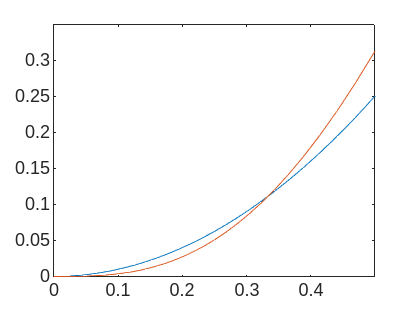


prob2 = zeros(1,100);
prob4 = zeros(1,100);
i = 1;

for f = p
        
    prob2(i) = pT(2,2,f);
    prob4(i) = pT(3,4,f) + pT(4,4,f);
    i = i + 1;

end

plot(p,prob2)
hold on 
plot(p, prob4)
hold off
axis([0 0.5 0 0.35])

## 6 a)



n = 8000;
X = 7;
p = 1/1000;
pX = pT(X,n,p)

pX = 0.1396

## b)


lambda = n* p;

pX2 = poisson(X, lambda) 

pX2 = 0.1396

## 7 a)


X = 0; % Nº de mensagens recebidas em 4 segundos
lambda = 15;
pX = poisson(X, lambda)  

pX = 3.0590e-07

## b)


X = 40;
pX = 0;
for i = 0:X
    pX = pX + poisson(i, lambda);
end 
p = 1- pX

p = 2.3434e-08

## 8



lambda = 0.02 * 100;
pX = 0;
for i = 0:1
    pX = pX + poisson(i, lambda);
end
pX

pX = 0.4060

## 9 a)



N = 1e5;
sigma = 2;
miu = 14;

X = randn(N,1)*sigma+miu;
mean(X)

ans = 14.0023

var(X)

ans = 4.0050

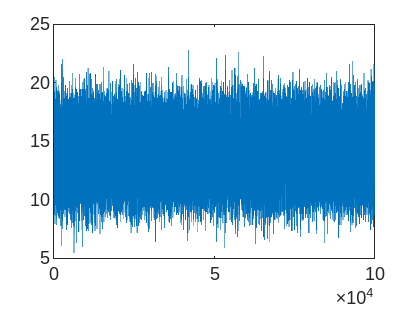


figure(1)
plot(X)

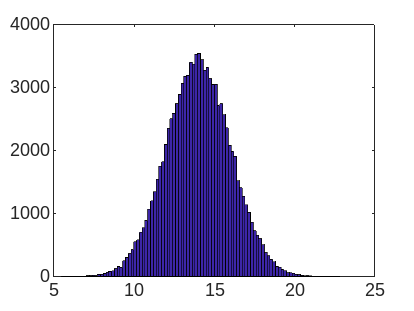

hist(X,100)


cfav = sum(X>12 & X<16);
p = cfav/N

p = 0.6828

pt = normcdf(16,14,2)-normcdf(12,14,2)

pt = 0.6827

## b)



cfav = sum(X>10 & X<18);
p = cfav/N

p = 0.9545

pt = normcdf(18,14,2)-normcdf(10,14,2)

pt = 0.9545

## c)



cfav = sum(X>=10 & X<=20);
p = cfav/N

p = 0.9761

pt = normcdf(20,14,2)-normcdf(10,14,2)

pt = 0.9759